% -----------------------------------------
% ICE for ODE
% LiXin
% 2022/4/1
% -----------------------------------------

Problem 1

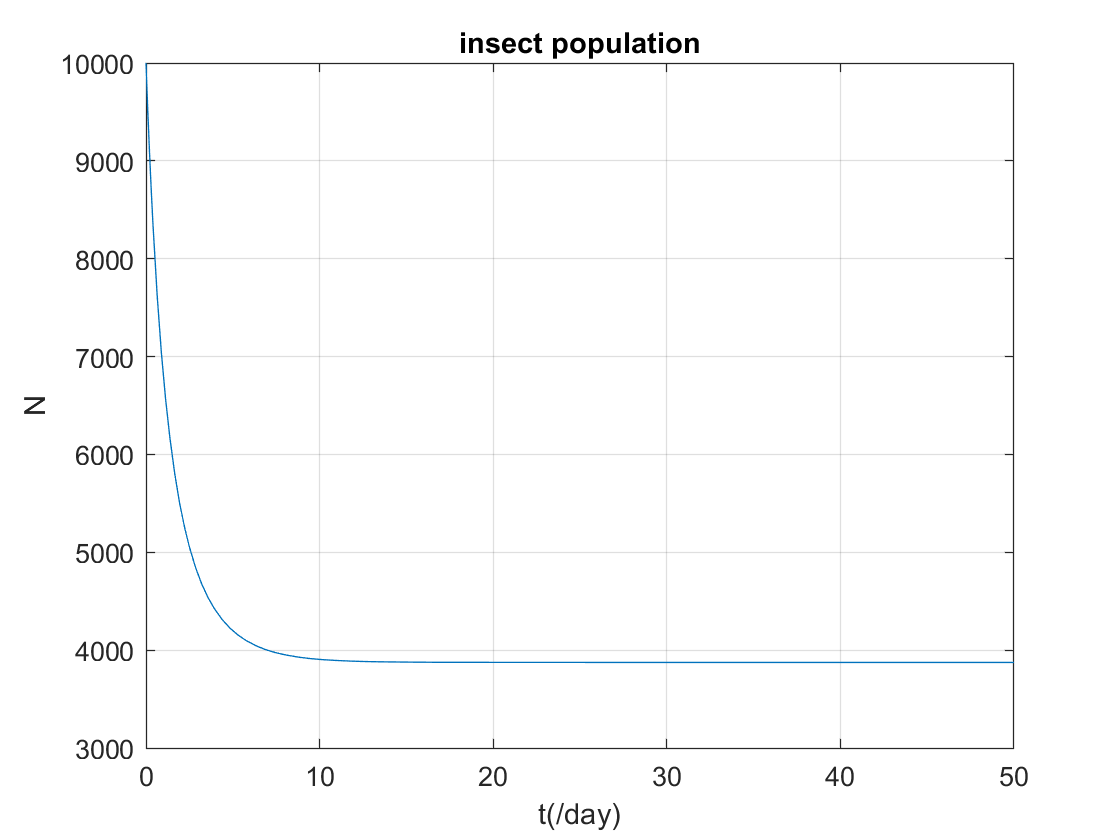

clear; close; clc;
tspan=[0 50];
R=0.55;
C=10000;
Nc=10000;
r=10000;
fun = @(t,N) R*N*(1-N/C)-r*N*N/(Nc^2+N^2);
[t,y]=ode45(fun,tspan,10000);
plot(t,y), title('insect population'), xlabel('t(/day)'), ylabel('N'), grid on;

for i = 1:size(y)
    if abs((y(i+1)-y(i))/y(i)) < 0.001
        break
    end
end
fprintf("steady population is %f, it take %f to get there", ...
    y(i), t(i))

steady population is 3883.215242, it take 12.699979 to get there

Problem 2

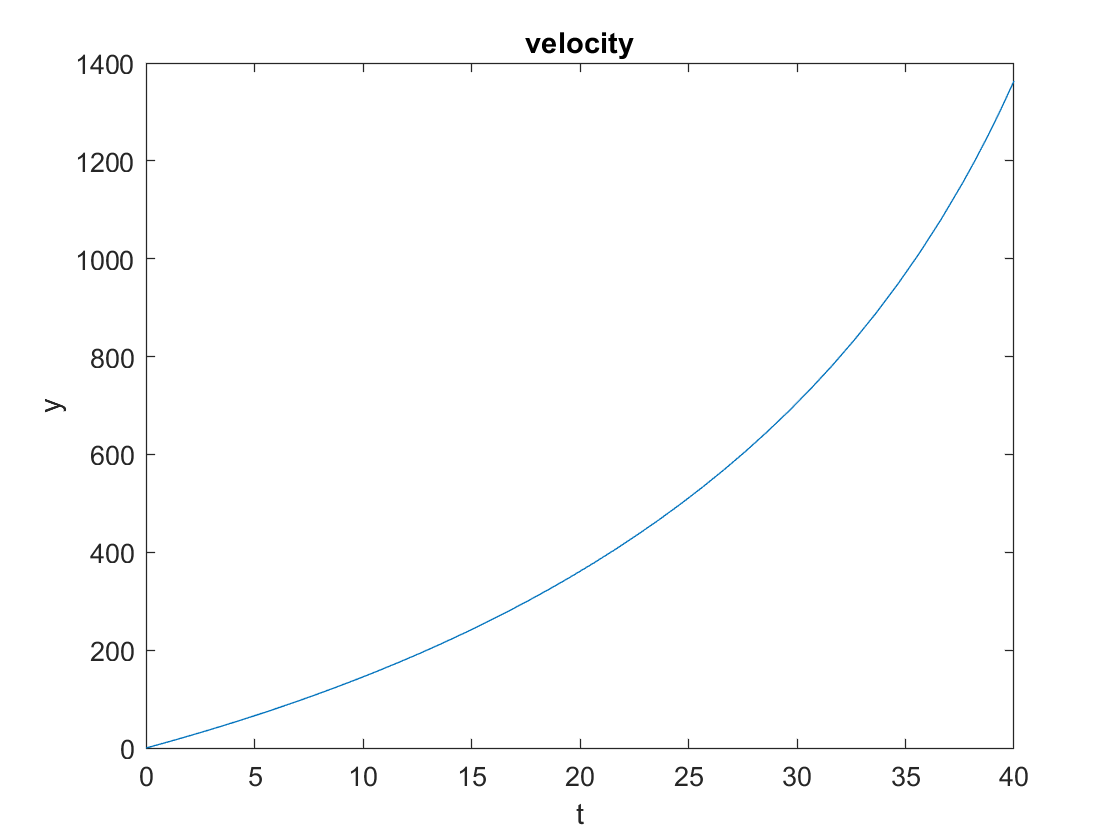

clear; close;clc
T=48000;
m0=2200;
R=0.8;
g=9.81;
b=40;
fun=@(t,v) (T-m0*(1-R*t/b)*g)/(m0*(1-R*t/b));
[n,y]=ode45(fun,[0 40],0);
figure
plot(n,y),title('velocity'),ylabel('y'),xlabel('t')

fprintf('The final velocity of a rocket is %f',y(end))

The final velocity of a rocket is 1363.350434

Problem 3

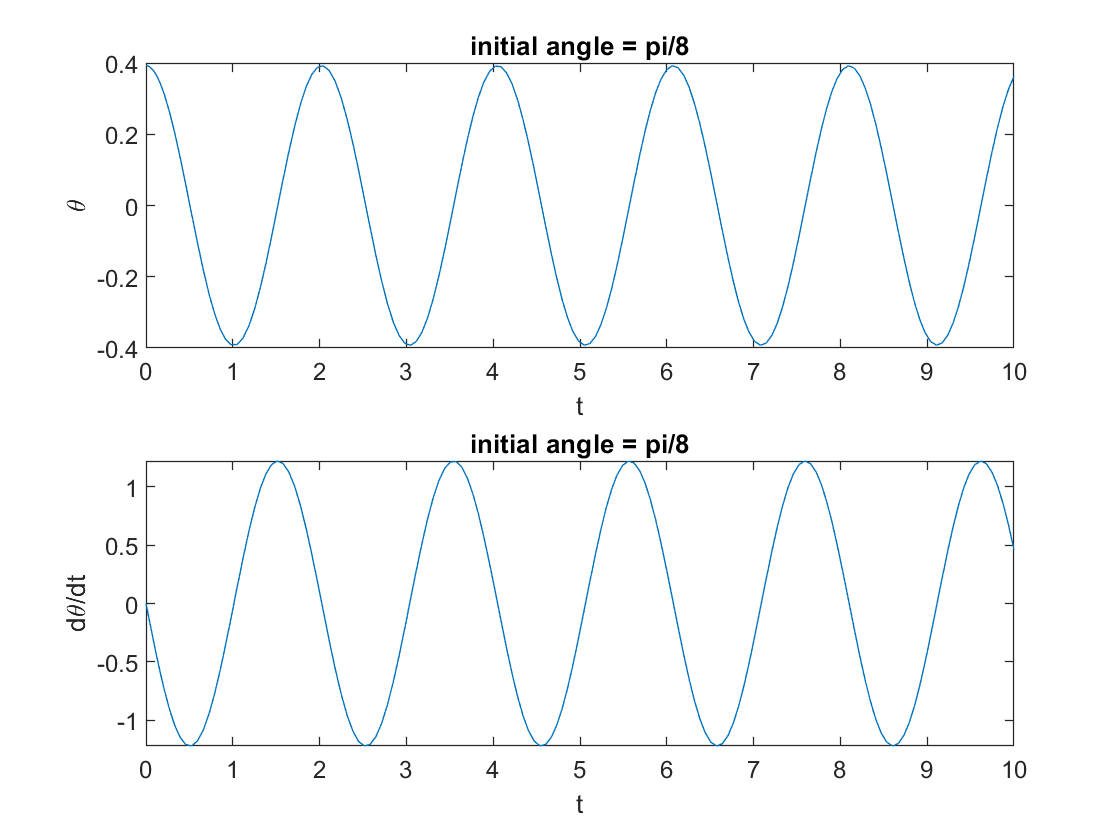

clear; close; clc;
[t,y]=ode45(@pendulum,[0 10],[pi/8 0]);
figure
subplot(2,1,1)
plot(t,y(:,1)), title('initial angle = pi/8'), xlabel('t'), ylabel('\theta');
subplot(2,1,2)
plot(t,y(:,2)), title('initial angle = pi/8'), xlabel('t'), ylabel('d\theta/dt');

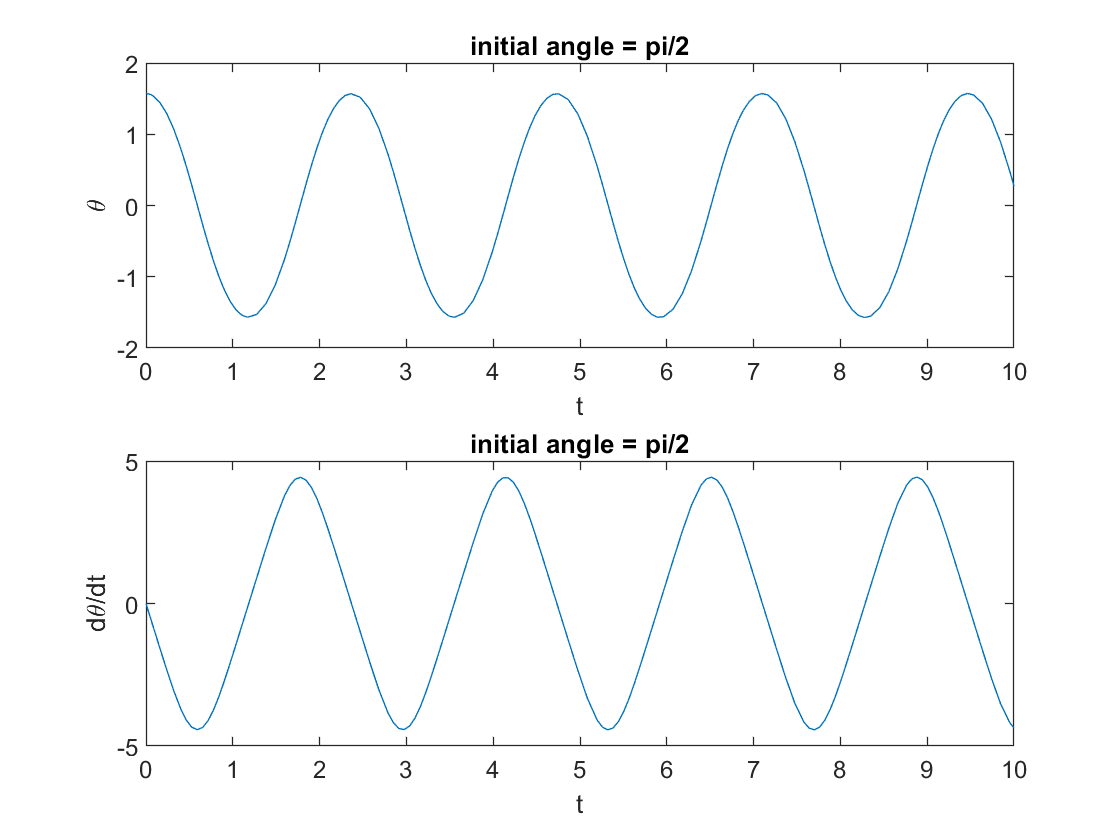

[t,y]=ode45(@pendulum,[0 10],[pi/2 0]);
figure
subplot(2,1,1)
plot(t,y(:,1)), title('initial angle = pi/2'), xlabel('t'), ylabel('\theta');
subplot(2,1,2)
plot(t,y(:,2)), title('initial angle = pi/2'), xlabel('t'), ylabel('d\theta/dt');

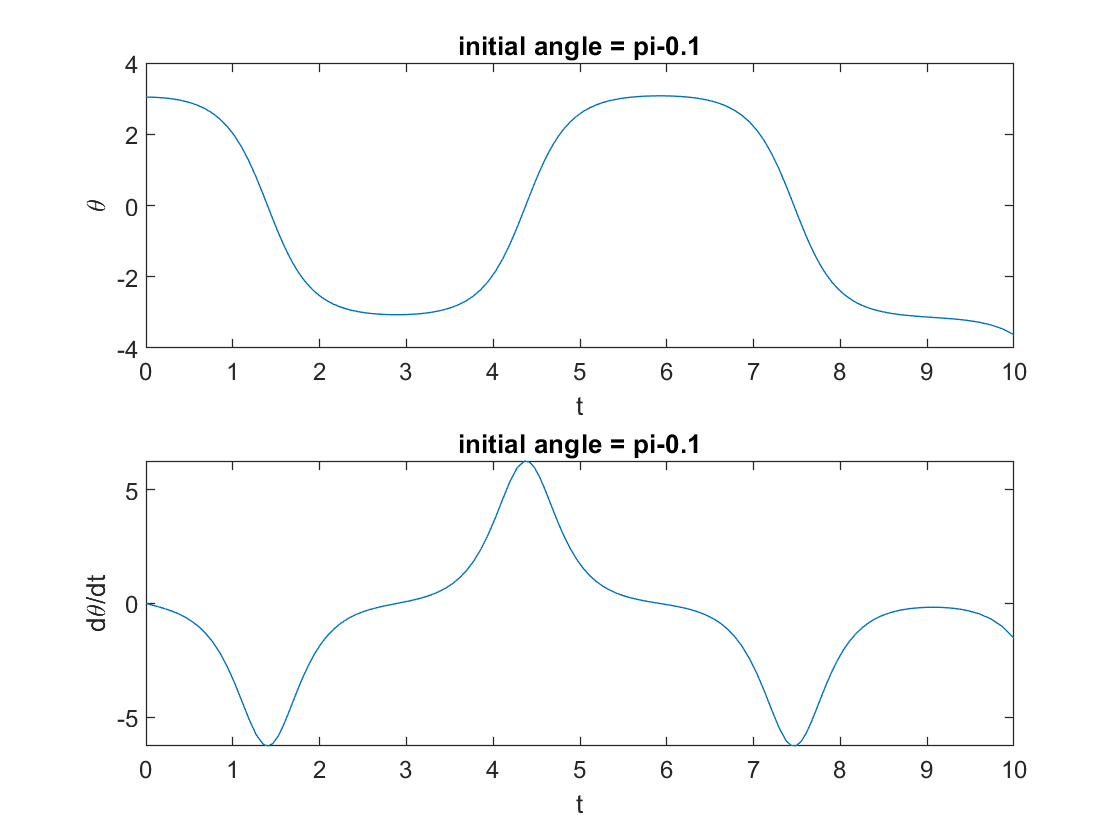

[t,y]=ode45(@pendulum,[0 10],[pi-0.1 0]);
figure
subplot(2,1,1)
plot(t,y(:,1)), title('initial angle = pi-0.1'), xlabel('t'), ylabel('\theta');
subplot(2,1,2)
plot(t,y(:,2)), title('initial angle = pi-0.1'), xlabel('t'), ylabel('d\theta/dt');

Problem 4

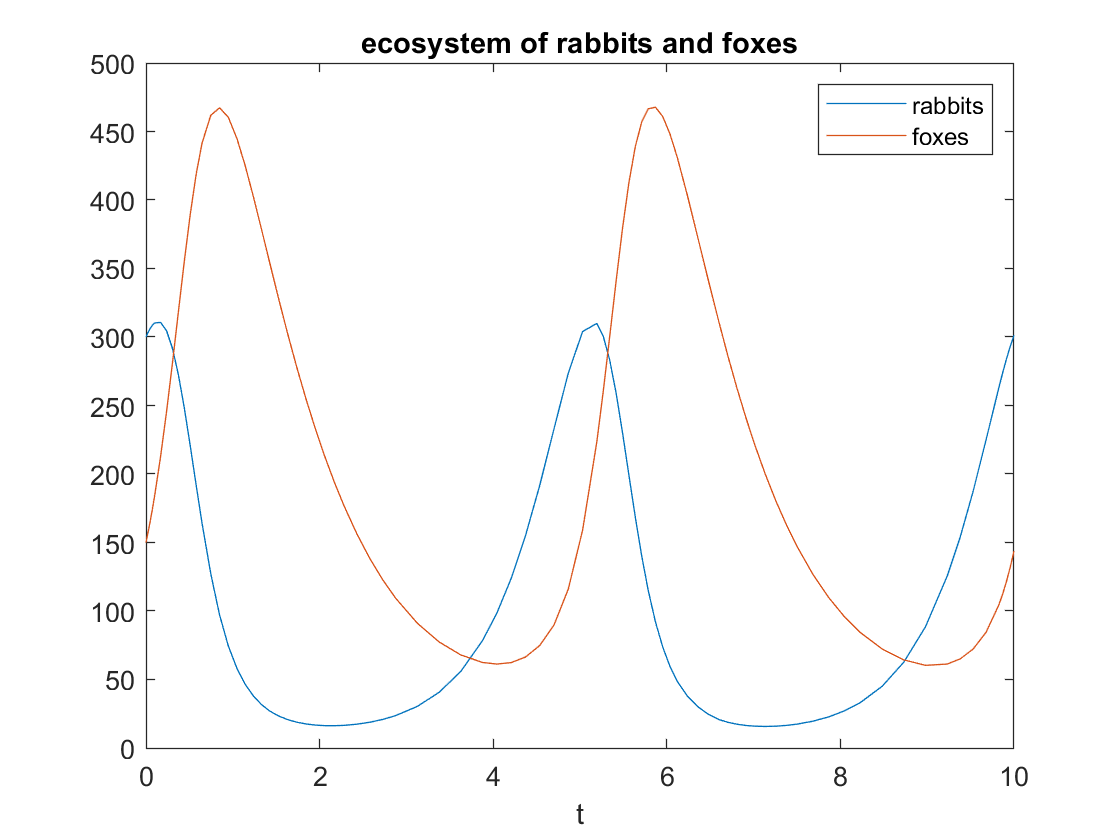

clear; close; clc;
[t y]=ode45(@rabbit_fox,[0 10],[300 150]);
figure
plot(t,y), legend('rabbits', 'foxes'), title('ecosystem of rabbits and foxes'), xlabel('t')

function dtheta_dt=pendulum(t,y)
    r=1;
    g=9.81;
    dtheta_dt=[y(2); -g/r*sin(y(1))];  
end

function rf=rabbit_fox(t,w)
a=0.01;
rf=[2*w(1)-a*w(1)*w(2);-w(2)+a*w(1)*w(2)];
end